Carlos_Alcaraz=one_player(data,"Carlos Alcaraz");
Novak_Djokovic=one_player(data,"Novak Djokovic");

resc=AHPTOPSIS3(table2array(Carlos_Alcaraz),1);
resn=AHPTOPSIS3(table2array(Novak_Djokovic),2);

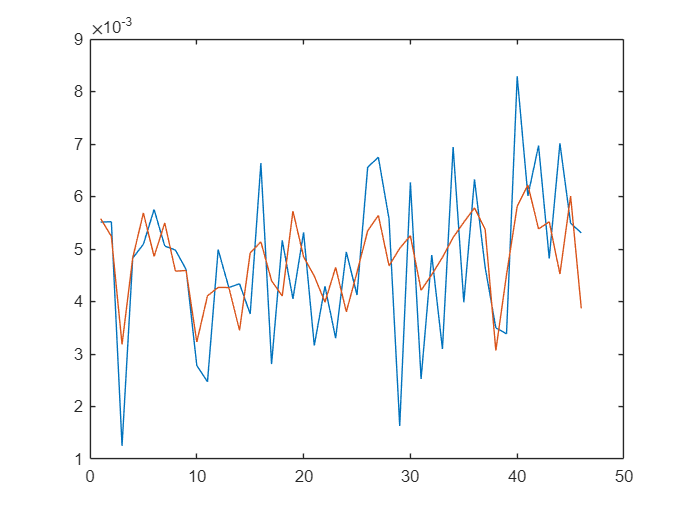

rescf=resc(length(resc)-46+1:length(resc));
resnf=resn(length(resn)-46+1:length(resn));
x=1:1:46;
plot(x,rescf,x,resnf)

diff=rescf-resnf;
corrcet=[];
for i=1:length(diff)
    if diff(i)*(data_cut2{i+1109-46,3}-1.5)<0
        corrcet(i)=1;
    else
        corrcet(i)=0;
    end
end
c=sum(corrcet)/46

c = 0.8696